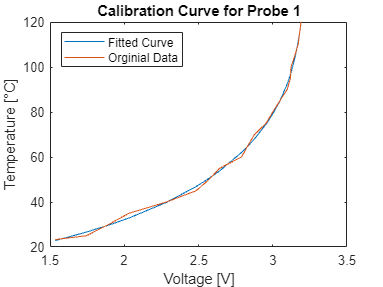

Temps = [23.3 25 30 35 40 45 50 55 60 65 70 75 80 85 90 95 100 105 110 115 120]';
v1 = [1.535 1.745 1.894 2.032 2.284 2.484 2.571 2.642 2.790 2.832 2.877 2.955 3.000 3.048 3.097 3.119 3.123 3.148 3.171 3.181 3.190]';
v2 = [1.577 1.755 1.842 2.003 2.223 2.403 2.500 2.571 2.723 2.771 2.826 2.903 2.952 3.000 3.055 3.084 3.097 3.123 3.148 3.161 3.171]';
v3 = 1.824;

% Probe_1_Voltages = v1;
% Probe_2_Voltages = v2;
% Calibration_Data = table(Temps,Probe_1_Voltages,Probe_2_Voltages)
% writetable(Calibration_Data,'CalibraitonData.txt','Delimiter','\t','WriteRowNames',true);
% type CalibraitonData.txt

R_T1 =9.75e3;
R_T2 = 9.76e3;
R_S1 = (R_T1*(3.3-v1))./v1;
R_S2 = (R_T2*(3.3-v2))./v2;


p1 = polyfit(log(R_S1/R_T1), 1./Temps, 4);
y1 = polyval(p1, log(R_S1/R_T1));
plot(v1, y1.^(-1));
hold on
plot(v1, Temps);
hold off
title("Calibration Curve for Probe 1")
xlabel("Voltage [V]")
ylabel("Temperature ["+char(176)+"C]")
legend("Fitted Curve", "Orginial Data","Location","northwest")
saveas(gcf, "Probe1Calib.jpg");

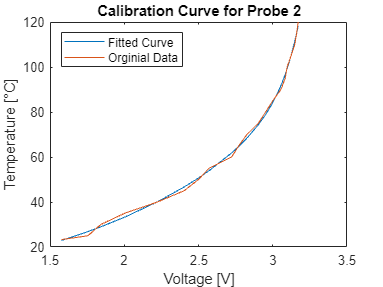


p2 = polyfit(log(R_S2/R_T2), 1./Temps, 4);
y2 = polyval(p2, log(R_S2/R_T2));
plot(v2, y2.^(-1));
hold on
plot(v2, Temps);
hold off
title("Calibration Curve for Probe 2")
xlabel("Voltage [V]")
ylabel("Temperature ["+char(176)+"C]")
legend("Fitted Curve", "Orginial Data","Location","northwest")
saveas(gcf, "Probe2Calib.jpg");

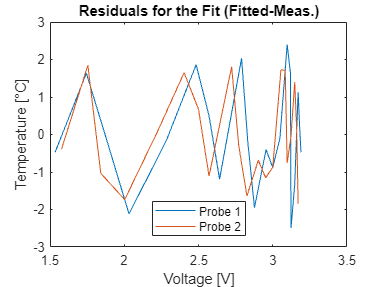


res1 = y1.^(-1)-Temps;
res2 = y2.^(-1)-Temps;
plot(v1, res1)
hold on
plot(v2, res2)
hold off
title("Residuals for the Fit (Fitted-Meas.)")
xlabel("Voltage [V]")
ylabel("Temperature ["+char(176)+"C]")
legend("Probe 1", "Probe 2","Location","south")
saveas(gcf, "ResidualPlot.jpg");